Generate an ARX estimate of the system represented by the three dater files using the least squares estimate method.

First we load in the data file and run the LSE to generate the system parameters for the ARX model.

load("second_order_system1.dat") % For the first data file
y = second_order_system1(:,3);
u = second_order_system1(:,2);
k = second_order_system1(:,1);
theta = zeros(4,501);
phi = zeros(4,501);
P = eye(4);
for i = 3:499
    phi(:,i) = [y(i-1) y(i-2) u(i-1) u(i-2)]';
    theta(:,i+1) = theta(:,i) + P*phi(:,i)/(1+phi(:,i)'*P*phi(:,i))*( ...
        y(i+1)-phi(:,i)'*theta(:,i));
    P = P - (P*phi(:,i)*phi(:,i)'*P)/(1+phi(:,i)'*P*phi(:,i));
end
y_est = [0 0 0 0;y(1) 0 u(1) 0;y(2:499) y(1:498) u(2:499) u(1:498)]*theta(:,500)+randn(500,1);
theta(:,500) %the identified parameters from the LSE

ans =     2.8844
   -1.9417
   -8.4089
   -8.4089


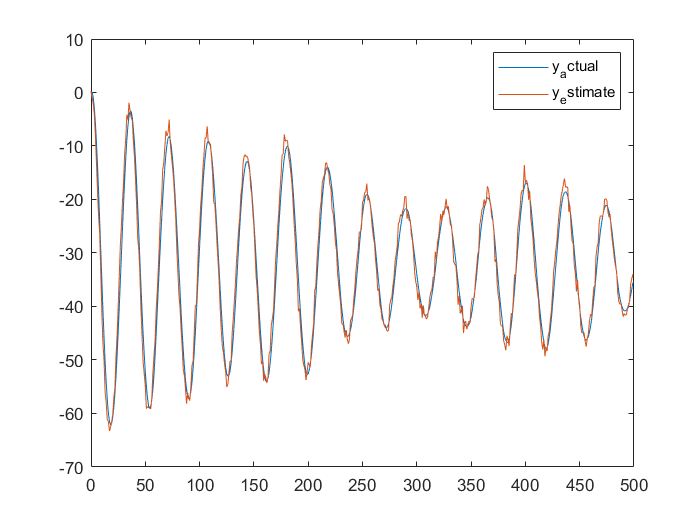

plot(k,y,k,y_est)               % compare actual data with results from LSE
legend('y_actual','y_estimate')

load("second_order_system2.dat") % For the second data file
y = second_order_system2(:,3);
u = second_order_system2(:,2);
k = second_order_system2(:,1);
theta = zeros(4,501);
phi = zeros(4,501);
P = eye(4);
for i = 3:499
    phi(:,i) = [y(i-1) y(i-2) u(i-1) u(i-2)]';
    theta(:,i+1) = theta(:,i) + P*phi(:,i)/(1+phi(:,i)'*P*phi(:,i))*( ...
        y(i+1)-phi(:,i)'*theta(:,i));
    P = P - (P*phi(:,i)*phi(:,i)'*P)/(1+phi(:,i)'*P*phi(:,i));
end
y_est = [0 0 0 0;y(1) 0 u(1) 0;y(2:499) y(1:498) u(2:499) u(1:498)]*theta(:,500)+randn(500,1);
theta(:,500) % the identified parameters from the LSE

ans =     2.6358
   -1.7329
   -7.4180
  -13.8123


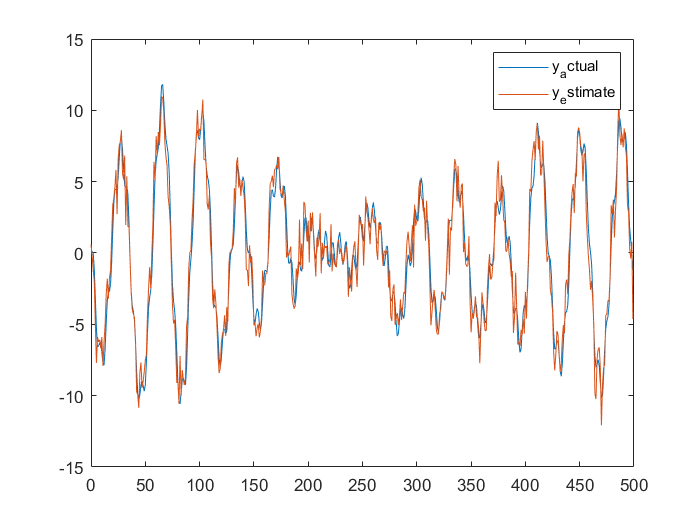

plot(k,y,k,y_est)                 % compare actual data with results from LSE
legend('y_actual','y_estimate') 

From the plots above, the parameters from the two data files are not the same. This is because the second data file shows more measurement noise than the first. So the parameters from second_order_system1 are the actual system parameters.

### Problem 1.4

The system is ARMAX so we will use the recursive prediction error method (RPEM) to generate the system parameters. By rewriting the system dynamics with $\hat{y_k }$, the system becomes ARX so we can use the LSE to get an estimte of the outputs with minimum prediction error. Also since the noise is i.i.d, the RPEM is just the LSE.

load("second_order_system3.dat") % For the second data file
y = second_order_system3(:,3);
u = second_order_system3(:,2);
k = second_order_system3(:,1);
theta = zeros(4,501);
phi = zeros(4,501);
P = eye(4);
for i = 3:499
    phi(:,i) = [y(i-1) y(i-2) u(i-1) u(i-2)]';
    theta(:,i+1) = theta(:,i) + P*phi(:,i)/(1+phi(:,i)'*P*phi(:,i))*( ...
        y(i+1)-phi(:,i)'*theta(:,i));
    P = P - (P*phi(:,i)*phi(:,i)'*P)/(1+phi(:,i)'*P*phi(:,i));
end
y_est = [0 0 0 0;y(1) 0 u(1) 0;y(2:499) y(1:498) u(2:499) u(1:498)]*theta(:,500);
theta(:,500) % the identified parameters from the LSE

ans =     0.9729
   -0.0590
   -0.0063
    0.0539


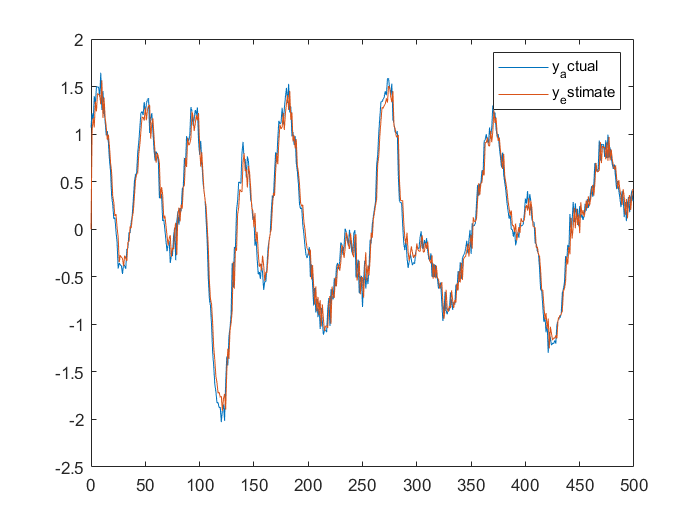

plot(k,y,k,y_est)              % compare actual data with results from LSE
legend('y_actual','y_estimate')

From the plots above we can see that the estimates from the LSE are almost the same ast the actual output data.